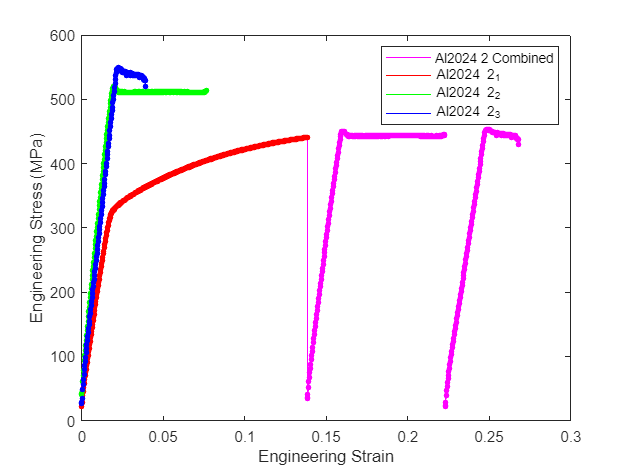

% THIS SCRIPT PLOTS MULTIPLE STRESS CURVES AND A COMBINED CURVE FOR STRAIN
% HARDENING OF A SINGLE MATERIAL, THIS EXAMPLE USES AL2024
% HERE'S SOME MATLAB TIPS TO HELP:
% Firstly, be sure to paste this code into a New Live Script, way easier to
% work here than directly in the Command Window
% Semicolons keeps variables from being outputted when they're created,
% makes it easy to keep your outputs clean and check variables when needed
% Select multiple lines and use CTRL+R to make them all comments!
% ATTRIBUTION: ChatGPT, Mathworks.com

% Open .csv files and retrieve data
al2024 = '/Users/vinay/Downloads/Al2024_2.csv';
al2024_data = readtable(al2024,'HeaderLines',9);

% Define material properties
al2024_width1 = 13.97;
al2024_width2 = 12.34;
al2024_width3 = 12.14;

al2024_thickness1 = 1.63;
al2024_thickness2 = 1.60;
al2024_thickness3 = 1.55;

al2024_length1 = 71.12;
al2024_length2 = 78.38;
al2024_length3 = 82.35;

% Extract data from tables, be careful here to use correct indices
% This particular dataset had an error in the first test, displacement was
% negative initially instead of 0, 6.2292 is added to offset this error
al2024_displacement1 = al2024_data{1:468,3} + 6.2292;
al2024_displacement2 = al2024_data{471:755,3};
al2024_displacement3 = al2024_data{758:912,3};

% These displacement values are offset to create continuous curve
al2024_cdisplacement2 = al2024_displacement2 + 6.2292 + 3.6224;
al2024_cdisplacement3 = al2024_displacement3 + 6.2292 + 3.6224 + 6.003;

al2024_force1 = al2024_data{1:468,4};
al2024_force2 = al2024_data{471:755,4};
al2024_force3 = al2024_data{758:912,4};

% This concatenates the values from all three tests for continuous curve
al2024_displacement = cat(1,al2024_displacement1, al2024_cdisplacement2, al2024_cdisplacement3);
al2024_force = cat(1,al2024_force1,al2024_force2,al2024_force3);

% Calculate engineering stress and strain values for each test and combined
al2024_egrstress1 = al2024_force1 ./ (al2024_width1 * al2024_thickness1); 
al2024_egrstrain1 = al2024_displacement1 ./ al2024_length1; 

al2024_egrstress2 = al2024_force2 ./ (al2024_width2 * al2024_thickness2); 
al2024_egrstrain2 = al2024_displacement2 ./ al2024_length2; 

al2024_egrstress3 = al2024_force3 ./ (al2024_width3 * al2024_thickness3);
al2024_egrstrain3 = al2024_displacement3 ./ al2024_length3; 

al2024_egrstress = al2024_force ./ (al2024_width1 * al2024_thickness1); 
al2024_egrstrain = al2024_displacement ./ al2024_length1; 

% Plot the data for each test and combined, scatter plot and line
al2024_plot = plot(al2024_egrstrain, al2024_egrstress, 'Color', 'magenta');
hold on
p1 = plot(al2024_egrstrain1, al2024_egrstress1, 'Color', 'red');
p2 = plot(al2024_egrstrain2, al2024_egrstress2, 'Color', 'green');
p3 = plot(al2024_egrstrain3, al2024_egrstress3, 'Color', 'blue');

scatter(al2024_egrstrain, al2024_egrstress, 10, 'filled', 'MarkerFaceColor', 'magenta', 'MarkerEdgeColor', 'magenta');
scatter(al2024_egrstrain1, al2024_egrstress1, 10, 'filled', 'MarkerFaceColor', 'red', 'MarkerEdgeColor', 'red');
scatter(al2024_egrstrain2, al2024_egrstress2, 10, 'filled', 'MarkerFaceColor', 'green', 'MarkerEdgeColor', 'green');
scatter(al2024_egrstrain3, al2024_egrstress3, 10, 'filled', 'MarkerFaceColor', 'blue', 'MarkerEdgeColor', 'blue');

xlabel('Engineering Strain');
ylabel('Engineering Stress (MPa)'); 

legend('Al2024 2 Combined','Al2024 2_1','Al2024 2_2','Al2024 2_3');

hold off